**Ionic Current Model of Bipolar Cells**

Set constants

tspan = [0, 1]; % Timespan. sec

Compute voltage

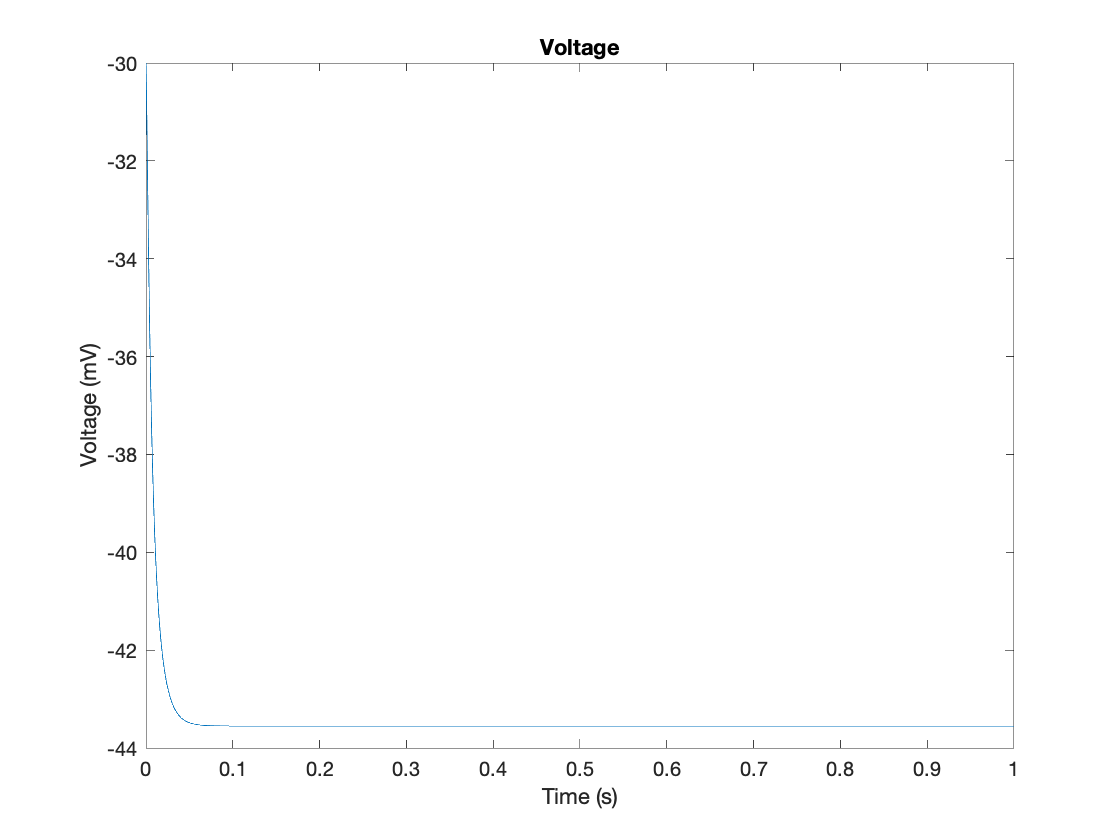

[t, res] = calcV(tspan,-30);
V = res(:,5);
Cas = res(:, 11);
plot(t, V)

% hold on
% 
% [tV_20, res] = calcV(tspan,-20);
% V_20 = res(:,5);
% plot(tV_20, V_20)
% 
title('Voltage')
xlabel('Time (s)')
ylabel('Voltage (mV)')

% legend('-30 pA injection','-20 pA injection')
% hold off

*Calcium current*

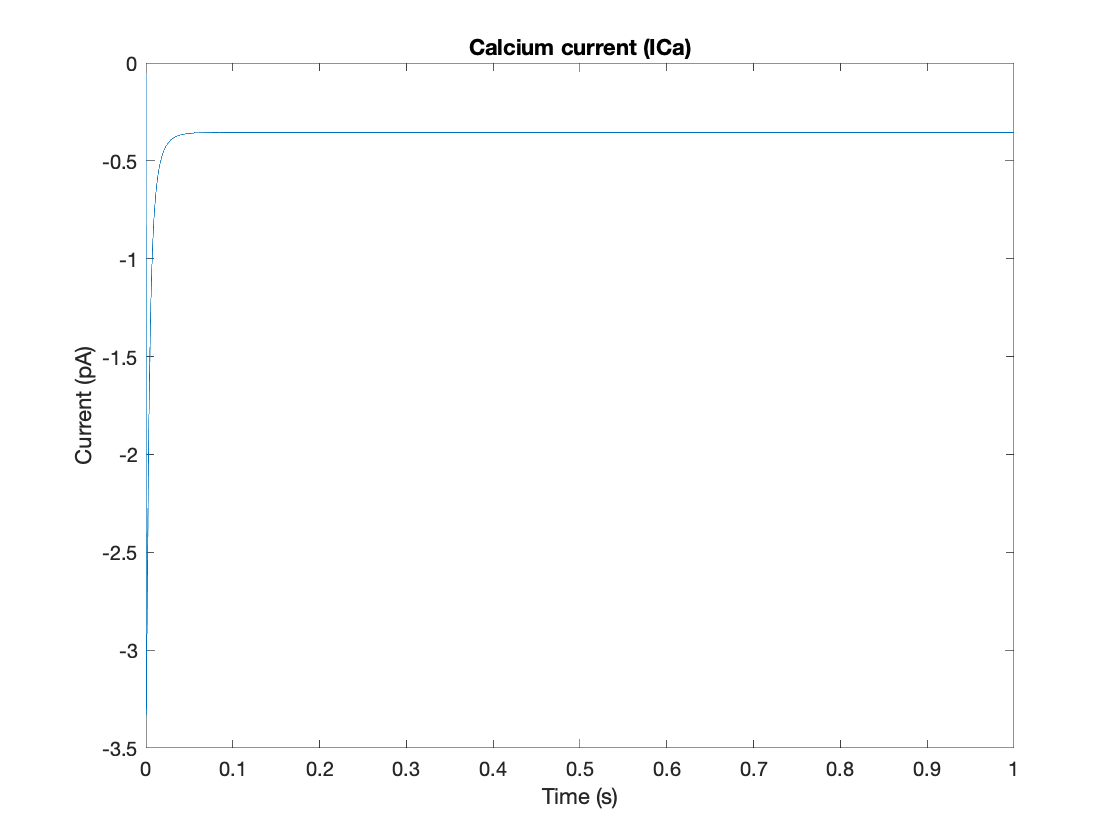

mCa = res(:,3);
ICa = calcICa(t, mCa, Cas, V);
plot(t, ICa)

title('Calcium current (ICa)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Calcium-dependent K current*

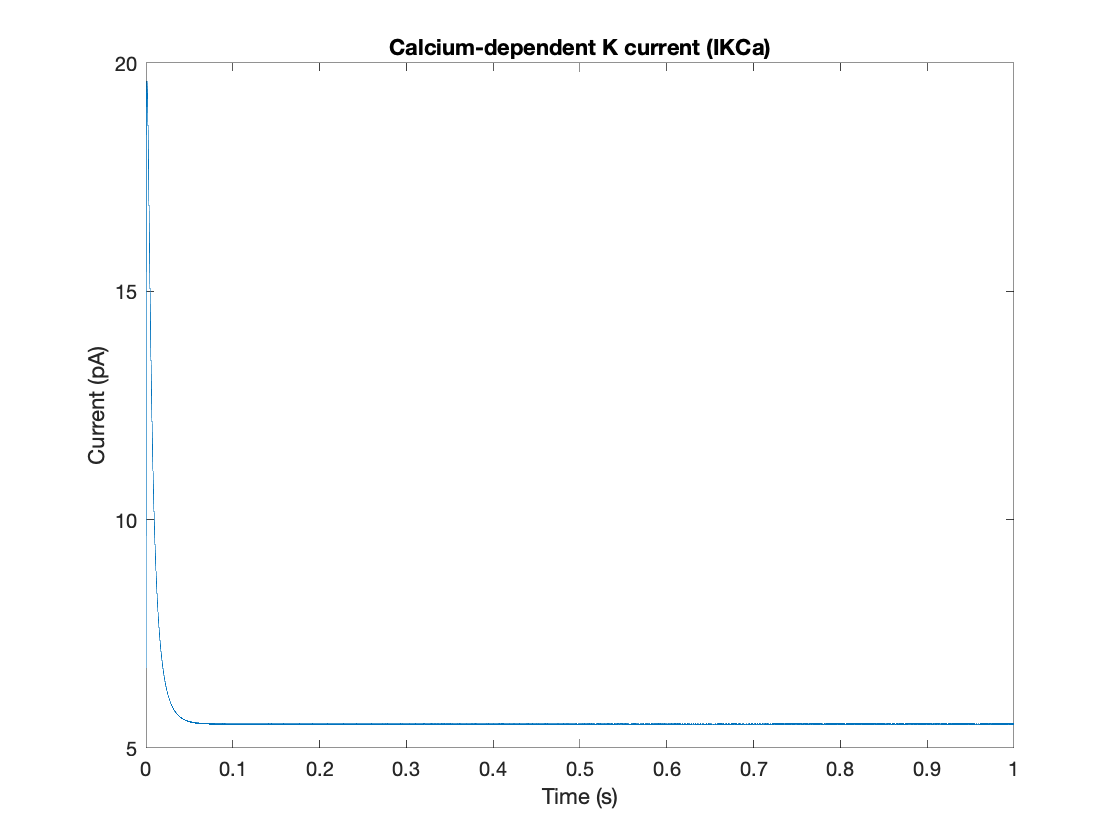

mKc = res(:,4);
IKCa = calcIKCa(t, mKc, Cas, V);
plot(t, IKCa)

title('Calcium-dependent K current (IKCa)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Delayed rectifying potassium current*

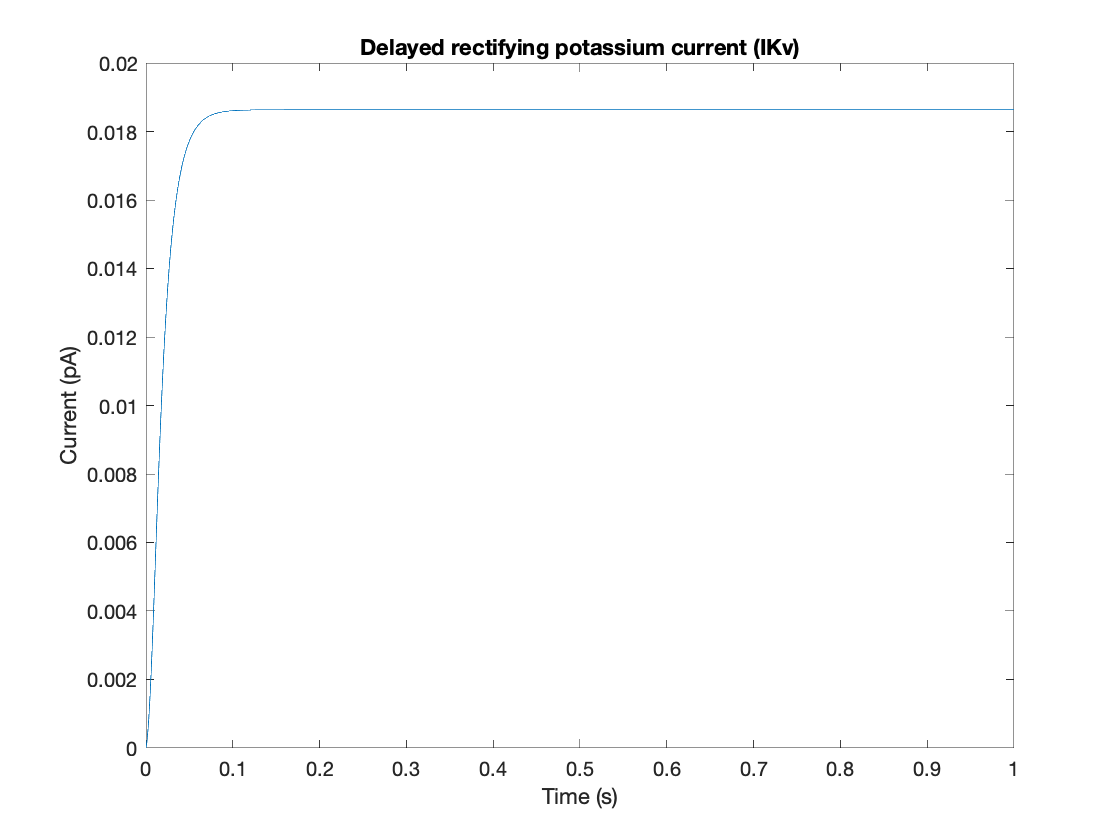

mKv = res(:,1);
hKv = res(:,2);
IKv = calcIKv(t, mKv, hKv, V);
plot(t, IKv)

title('Delayed rectifying potassium current (IKv)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Hyperpolarization activated current*

O1 = res(:,8);
O2 = res(:,9);
O3 = res(:,10);
Ih = calcIh(t, O1, O2, O3, V);

Ih =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


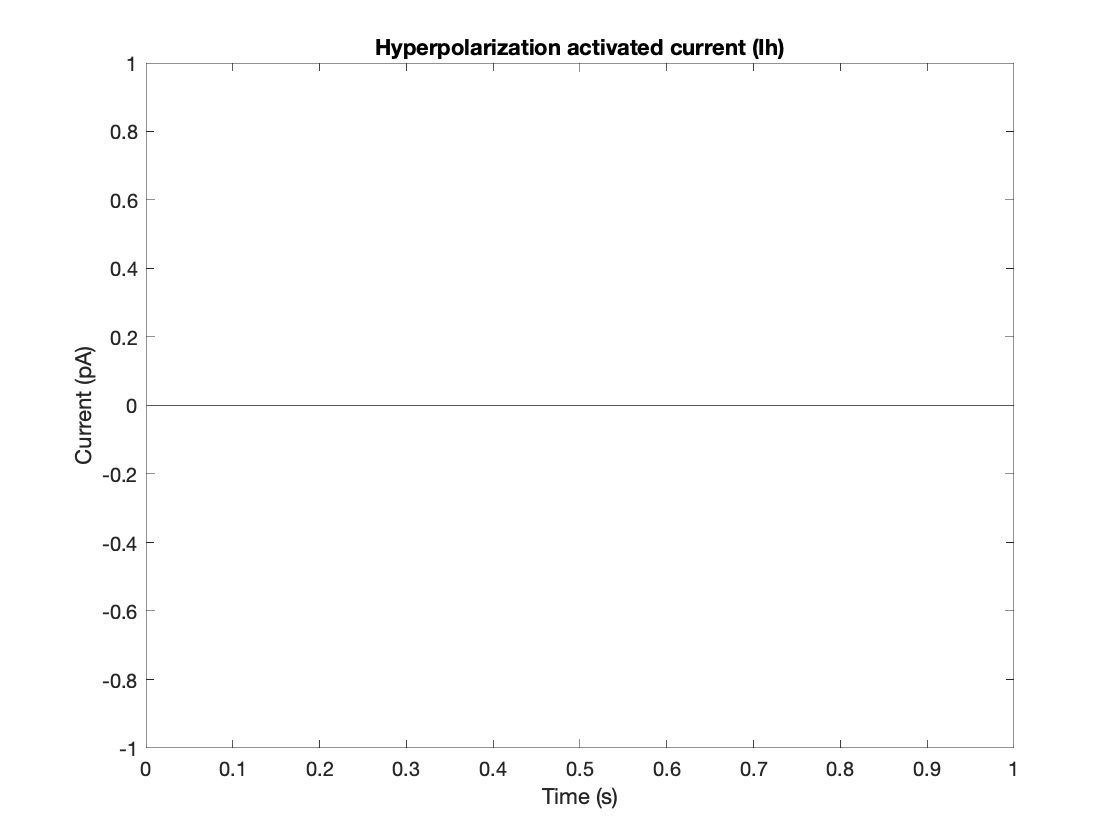

plot(t, Ih)

title('Hyperpolarization activated current (Ih)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Leakage current*

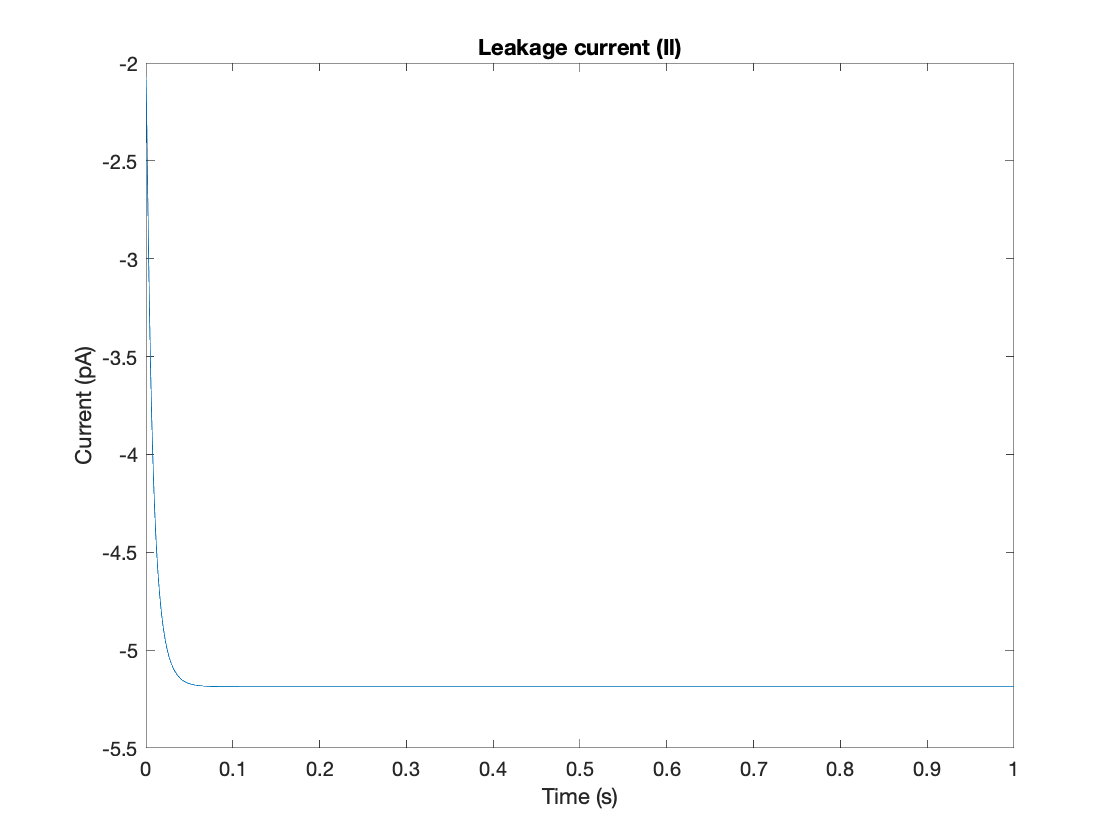

Il = calcIl(V);
plot(t, Il)

title('Leakage current (Il)')
xlabel('Time (s)')
ylabel('Current (pA)')

*Total ionic current*

% totalI = IKv+Ih+ICa+IKCa+Il+IA; % add injection current too

Requested 89288573x89288573 (59399375.8GB) array exceeds maximum array size preference. Creation of arrays greater than this limit may take a long time and cause MATLAB to become unresponsive. See array size limit or preference panel for more information.

% plot(t, totalI)
% 
% title('Total ionic current')
% xlabel('Time (s)')
% ylabel('Current (pA)')